# MEM 355 Final Project - Group 9 - 202135

Names here at some point

## Scenario 

A Company Cosmos XYZ, is studying a means of transportation of astronauts during their  EVAs. It proposes to use a thruster for linear translation and a torquer to maintain posture, both mounted on a backpack. You have been asked to evaluate the feasibility of such a  concept. As a preliminary investigation you have been provided with a mathematical model  of the astronaut-backpack system, schematics, and relevant numerical values. 

### **System Description **

$\mathit{\mathbf{M}}\ddot{\;q} +\mathit{\mathbf{D}}\dot{\;q} +\mathit{\mathbf{K}}\;q=\mathit{\mathbf{B}}{\;T}_c +\mathit{\mathbf{F}}\;\mathit{\mathbf{f}}$; $q=\left\lbrack \begin{array}{c}
\theta \\
\psi 
\end{array}\right\rbrack$    

The equations of motion for an astronaut in deep space (no gravity effects) with the following assumptions made: 

A1. The body/backpack system is idealized as two rigid bodies connected by a line  hinge at the hip joint. The hinge has spring restraint *k *and viscous damping *c*. 

A2. The control torque applied from a reaction wheel is *T**c *and the force *f *is  obtained from the thruster. 

A3. An angular position **sensor **measures the pitch θ (in radians) of the torso. 

Numerical Values 

(in consistent units: *kg, N, m, **rad**, sec*) 

$\mathit{\mathbf{M}}=\left\lbrack \begin{array}{cc}
60\ldotp 1429 & 18\ldotp 5714\\
18\ldotp 5714 & 14\ldotp 28\ldotp 57
\end{array}\right\rbrack$,$\mathit{\mathbf{D}}=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 2
\end{array}\right\rbrack$,$\mathit{\mathbf{K}}=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 1000
\end{array}\right\rbrack$

$\mathit{\mathbf{B}}=\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$,$\mathit{\mathbf{F}}=\left\lbrack \begin{array}{c}
-0\ldotp 042857\\
-0\ldotp 071429
\end{array}\right\rbrack$

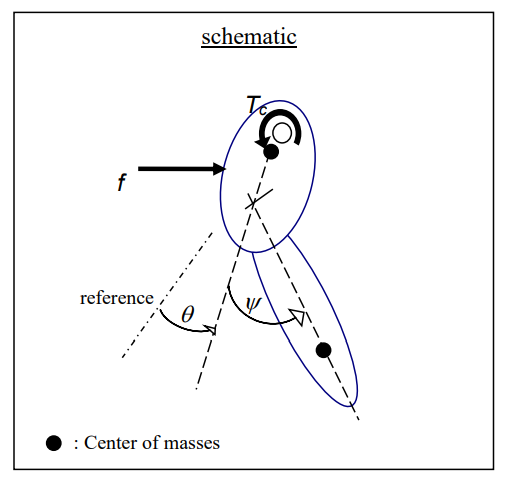

clc, clear all
% Initialize givens
M = [60.1429,18.5714;18.5714,14.2857];
D = [0,0;0,2];
K = [0, 0;0,1000];

B = [1;0];
F = [-0.042857;-0.071429];

### **Problem Statements **

1. Obtain a state space representation of the system, and identify *A, B *(treat both *T**c *and *f *as inputs), and *M (measurement matrix) *matrices. Use $\mathit{\mathbf{x}}=\left\lbrack \begin{array}{c}
q\\
\dot{q} 
\end{array}\right\rbrack \;$for the states. 

syms f(theta) f(phi) f(T_c) f(force)
q_state = [f(theta) f(phi)]'; 
q_state_dot = [diff(q_state(1)) diff(q_state(2))]';
q_state_dot_dot = [diff(q_state_dot(1)) diff(q_state_dot(2))]';
big_eqn = M .* q_state_dot_dot + D .* q_state_dot + K .* q_state == B .*  f(T_c) + F .*  f(force);

% solved by hand
C = (-M(2,1)*M(1,2)/(M(1,1)))+M(2,2); % only relevant for lines 18-21

%state space
A = [0 1;-K(2,2)/C -D(2,2)/C] % A matrix
B_f = [0; (-F(1) +F(2))/C];
B_Tc = [0; (-B(1)/C) ];
B = [B_f,B_Tc] % B matrix
C = [1,0];
D = [0,0];

2a. Compute the eigenvalues and eigenvectors of *A*. Is this system asymptotically stable? Why, or why not ? Explain. 

[eig_vals,eig_vects] = eig(A)

        The eigenvalues are complex, whose real part positive points are spiral sources (unstable at 0.9958) and whose real part negative points are spiral sinks (asymptopically stable at -0.001). 

2b. Determine the frequency and the damping ratio associated with oscillatory modes,  if any. 

tf_final = ss(A,B,C,D) % Ax + Bu
[wn,zeta,p] = damp(tf_final) % natural frequencies, damping ratio, poles

The poles of `tf_final` are complex conjugates lying in the left half of the s-plane. The corresponding damping ratio is less than 1. Hence, `tf_final` is an underdamped system.

3a. Is this system completely controllable with *T**c *and *f ? *

control_mat_both = ctrb(A,B);
thrust_torque_bool = length(control_mat_both)-rank(control_mat_both) == 0

**No.**

3b. Is this system completely controllable with **only *****T******c ***(i.e., with *f = 0*) ? 

control_mat_thrust = ctrb(A,B_f);
thrust_bool = length(control_mat_thrust)-rank(control_mat_thrust) == 0

**Yes.**

3c. Is this system completely controllable with **only *****f ***(i.e., with *T**c **= 0*) ? 

control_mat_torque = ctrb(A,B_Tc);
torque_bool = length(control_mat_torque)-rank(control_mat_torque) == 0

**Yes.**

3d. Is this system observable from the position sensor? 

observe_sensor = obsv(A,C);
sensor_bool = length(observe_sensor)-rank(observe_sensor) == 0

**Yes.**

You may ignore the force *f *in what follows. 

4. Using **only the torquer as the actuator**, design an observer based controller to orient the torso (theta) at the specified “set-point,” while satisfying other team specific specifications given in the table below. All specs are in consistent units.  Note the **set point is in degrees**. 

Follow this sequence: 

a. Design a full-state feedback control to meet settling time and OS specs. 

B_nof = [0,0; 0, B_Tc(2)] % only the torquer

% choosing new eigenvalues / determine an appropriate gain controller
ts = 30; % settling time in seconds
OS = 16/100; % 16 percent overshoot
% % zeta = -ln(OS)/sqrt(pi^2 + ln^2(OS))
% % Ts = 4 / zeta*wn
syms zeta w_n
damping_ratio_condition = OS == exp(-pi*zeta/sqrt(1-power(zeta,2)));
zeta = vpa(solve(damping_ratio_condition,zeta));
spec_zeta = double(zeta(1)) % system damping ratio
settling_time_condition = ts == 4 / (zeta(1) * w_n);
spec_wn = double(vpa(solve(settling_time_condition,w_n))) % natural frequency (radians/second)

% find poles
poles_spec = [-spec_zeta*spec_wn + i*sqrt(1-power(spec_zeta,2)); -spec_zeta(1)*spec_wn - i*sqrt(1-power(spec_zeta,2))]

These poles are the new eigenvalues for our system specifications, placed as G (our controllable/regulator gain.) System is asymptotically stable.

% These poles are the new eigenvalues for our system specifications, placed
% as G (our controllable/regulator gain.) 

System is asymptotically stable.

G = place(A,B_nof,poles_spec)
A_cl = A-(B_nof*G);
cPlant = ss(A_cl,B_nof,C,D) % our new Ax + Bu 
step(cPlant)
stepinfo(cPlant)

b. Design an appropriate estimator. 

You are required to show the efficiency of your estimator/observer by plotting the estimation error (these were denoted by $\overset{~}{\dot{x} }$ in class) for all states, for arbitrary, reasonable, non-zero initial conditions on the plant states. 

poles_est = poles_spec*6; 
F = place(A',C', poles_est)
A_cl2 = A_obs + F.*B_obs
cPlant = ss(A_cl2, B_nof, C, D)
step(cPlant),stepinfo(cPlant)
% [yc,tc,xc] = lsim() 

c. Construct the closed loop system and determine the set-point control. 

d. Simulate to verify the performance. In all likelihood, you will need to adjust the eigenvalues locations and the speed of the estimator to satisfy all the specifications. 

5. Demonstrate the function of your design by using simulations under zero initial  conditions. Note: the thruster is ignored in these simulations . 

function[Nbar]=rscale(A,B,C,D,K)
% Given the single-input linear system: 
%       .
% 		x = Ax + Bu
%   	y = Cx + Du
% and the feedback matrix K,
% 
% the function rscale(A,B,C,D,K) finds the scale factor N which will 
% eliminate the steady-state error to a step reference 
% using the schematic below:
%
%                         /---------\
%      R         +     u  | .	    |
%      ---> N --->() ---->| X=Ax+Bu |--> y=Cx ---> y
%                -|       \---------/
%                 |             | 
%                 |<---- K <----|
%
%8/21/96 Yanjie Sun of the University of Michigan
%        under the supervision of Prof. D. Tilbury
%
s = size(A,1);
Z = [zeros([1,s]) 1];
N = inv([A,B;C,D])*Z';
Nx = N(1:s);
Nu = N(1+s);
Nbar=Nu + K*Nx;
end

Your plots should show that (1) the torso orientation is at the requested set-point, (2) the torque does  not exceed its specification, (3) calculated (from the plot) OS of torso excursions  is within or near the specification.  

6. Obtain the response of all the states (for example, to answer questions like: how  do the legs move, are they vibrating , etc).

error_vals = [-100:100]
plot(real(eig((A-bPlant*C')) *error_vals),imag(eig((A-bPlant*C')) *error_vals))
xlabel('real')
ylabel('imag')

c. Construct the closed loop system and determine the set-point control. 

d. Simulate to verify the performance. In all likelihood, you will need to adjust the eigenvalues locations and the speed of the estimator to satisfy all the specifications. 

5. Demonstrate the function of your design by using simulations under zero initial  conditions. Note: the thruster is ignored in these simulations . 

Your plots should show that (1) the torso orientation is at the requested set-point, (2) the torque does  not exceed its specification, (3) calculated (from the plot) OS of torso excursions  is within or near the specification.  

6. Obtain the response of all the states (for example, to answer questions like: how  do the legs move, are they vibrating , etc).